clear; clc; clear path; close all;
addpath ../../funcs/.

zeta = 0.1;
omega = 1000;
s = tf([1 0],1);
Ps = (2*zeta*omega*s+omega^2)/(s^2*(s^2+2*zeta*omega*s+omega^2));

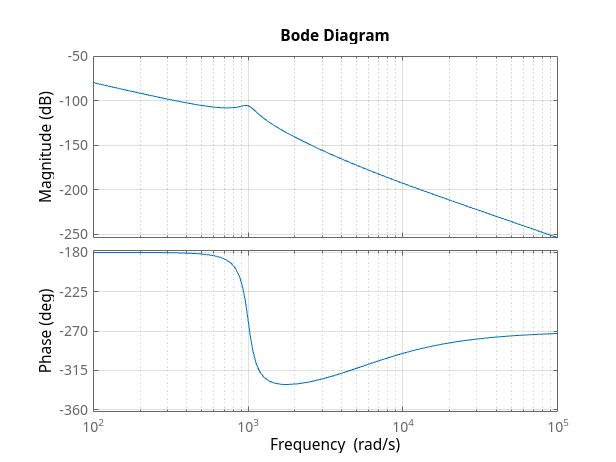

figure(1); clf; hold on;
bode(Ps)
grid on;

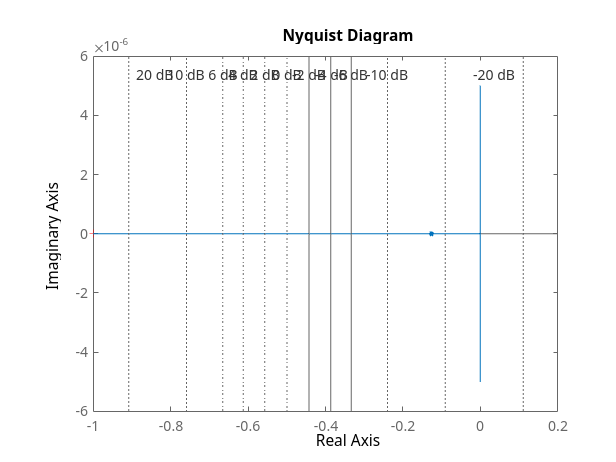

figure(2); clf; hold on;
nyquist(Ps)
grid on;

[z,p,k] = tf2zp([200 1e6],[1 200 1e6 0 0]);
fprintf("zeros at:\n%d",z);

zeros at:
-5000

fprintf("Poles at:\n")

Poles at:


for i=1:length(p)
    fprintf("%5.0f + %5.0f i\n",real(p(i)),imag(p(i)));
end; clear i;

    0 +     0 i
    0 +     0 i
 -100 +   995 i
 -100 +  -995 i


fprintf("Gain:\n %d",k);

Gain:
 200

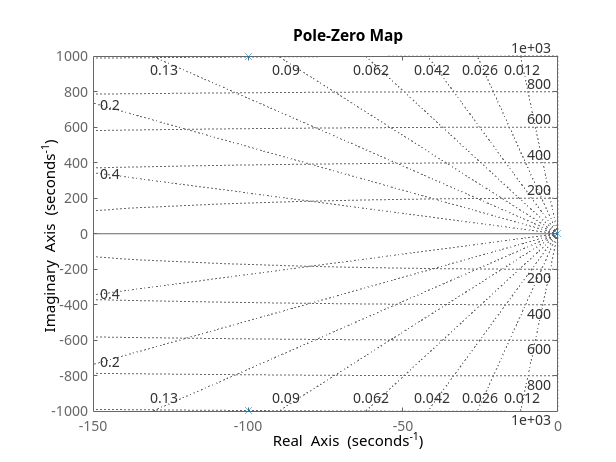

figure(3);clf;
pzmap(Ps)
axis([-150 0 -1000 1000])
grid on;

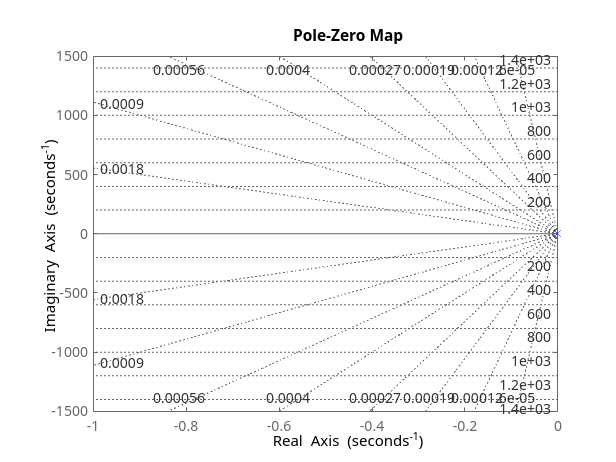


figure(4);clf;
pzplot(Ps,'*')
axis([-1 0 -1500 1500])
grid on;

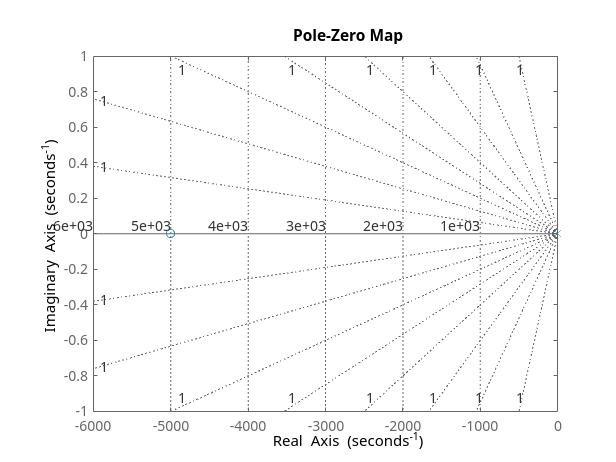

figure(5);clf;
pzplot(Ps)
axis([-6000 0 -1 1])
grid on;

From the root locus gain of the uncontrolled plant we see instability arising at k(29)=6.9104e+03. This is the maximum feedback gain that does not yet cause positive real part in any if thei eigenvalues.

actually, no any gain is too much

[r,k] = rlocus(Ps)

r = 1.0e+05 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0001i   0.0000 + 0.0001i   0.0000 + 0.0001i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0003i   0.0000 + 0.0004i   0.0000 + 0.0006i   0.0000 + 0.0008i   0.0000 + 0.0012i   0.0000 + 0.0016i   0.0000 + 0.0023i   0.0000 + 0.0034i   0.0001 + 0.0051i   0.0002 + 0.0054i   0.0002 + 0.0056i   0.0003 + 0.0058i   0.0004 + 0.0061i   0.0005 + 0.0062i   0.0006 + 0.0063i   0.0007 + 0.0064i   0.0009 + 0.0066i   0.0011 + 0.0067i   0.0013 + 0.0069i   0.0016 + 0.0071i   0.0020 + 0.0073i   0.0031 + 0.0079i   0.0038 + 0.0084i   0.0055 + 0.0096i   0.0072 + 0.0111i
   0.0000 + 0.0000i   0.0000 - 0.0

k = 1.0e+14 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


figure(6); clf;
% subplot(2,1,1)
% rlocusplot(Ps); grid on;


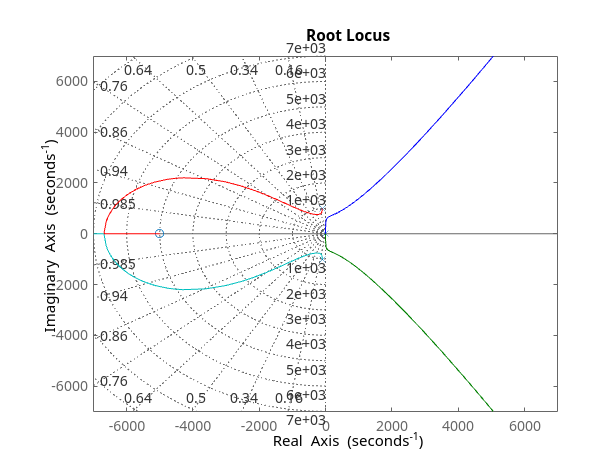

% subplot(2,1,2)
rlocusplot(Ps); grid on;
axis([-1 1 -1 1]*7E3)

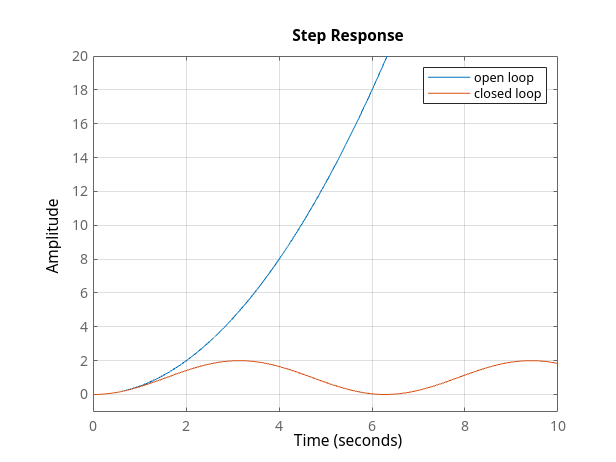

figure(8); clf; hold on;
Cs = pidGen(0,0, 100, 200 , 1 );
% step(Cs*Ps/(1+Cs*Ps),.1);
Te = 10;
step(Ps,Te);
step(Ps/(1+Ps),Te); grid on;
axis([0 Te -1 20])
legend("open loop","closed loop","Location","northeast")

xi = 0.690108;
wn = 1;
desiredPoles = [-xi*wn+i*wn*sqrt(1-xi^2); -xi*wn- i*wn*sqrt(1-xi^2)]

desiredPoles =   -0.6901 + 0.7237i
  -0.6901 - 0.7237i


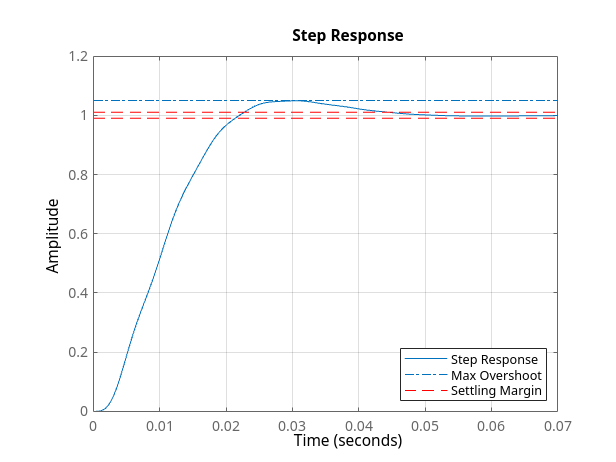

% Cs = pidGen(0, 0, 80, 150,1);
Cs = pidGen(0, 0, 106, 200,1);
% Cs = pidGen(1, .2, 1, 1,1);
figure(9); clf; hold on;
step(Cs*Ps/(1+Cs*Ps))
plot([0 1],[1.05 1.05],'-.')
plot([0 1],[1.01 1.01],'r--')
plot([0 1],[.99 .99],'r--')
legend('Step Response', 'Max Overshoot', 'Settling Margin',"Location",'southeast')
grid on;

info = stepinfo(Cs*Ps/(1+Cs*Ps))

info = struct with fields:
         RiseTime: 0.0138
    TransientTime: 0.0405
     SettlingTime: 0.0405
      SettlingMin: 0.9149
      SettlingMax: 1.0491
        Overshoot: 4.9125
       Undershoot: 0
             Peak: 1.0491
         PeakTime: 0.0306
